# DRS Project Team 4 force regression

clc;
close all;
clear all;

## Paper data

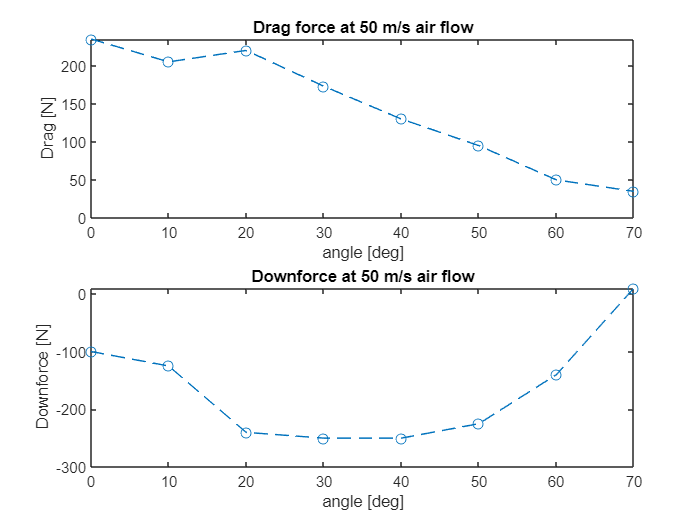

% these data are taken at 180 kmh wind speed. We need to find
% a curve that fits well the points and we need to scale it
% for all speeds

angle = 0:10:70;
drag = -[-235,-205,-220,-173,-130,-95,-50,-35]; % - [] to flip axis
downforce = [-100,-125,-240,-250,-250,-225,-140,10];
figure
subplot(2,1,1)
plot(angle,drag,'o--')
title('Drag force at 50 m/s air flow')
xlabel('angle [deg]')
ylabel('Drag [N]')
subplot(2,1,2)
plot(angle,downforce,'o--')
title('Downforce at 50 m/s air flow')
xlabel('angle [deg]')
ylabel('Downforce [N]')

## Linear regression of drag

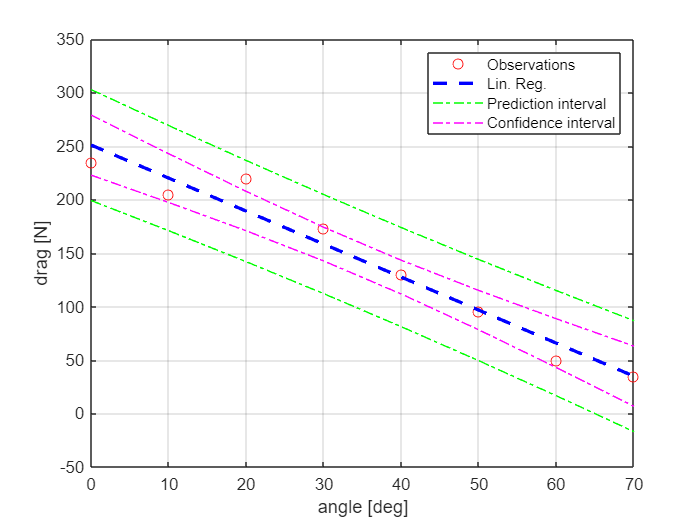

mdl = fitlm(angle',drag',"linear");

[drag_hat,ci_drag]=predict(mdl,angle',"Alpha",0.05,"Prediction","curve");
[~,cp_drag]=predict(mdl,angle',"Alpha",0.05,"Prediction","observation");

figure
plot(angle,drag,"or");
hold on
plot(angle,drag_hat,"--b","LineWidth",2)
plot(angle,cp_drag(:,1),"-.g")
plot(angle,cp_drag(:,2),"-.g")
plot(angle,ci_drag(:,1),"-.m")
plot(angle,ci_drag(:,2),"-.m")
xlabel('angle [deg]');
ylabel('drag [N]');
legend(["Observations","Lin. Reg.","Prediction interval","","Confidence interval",""])
grid();
hold off;

## Resultant flap momentum reduced at rotation axis

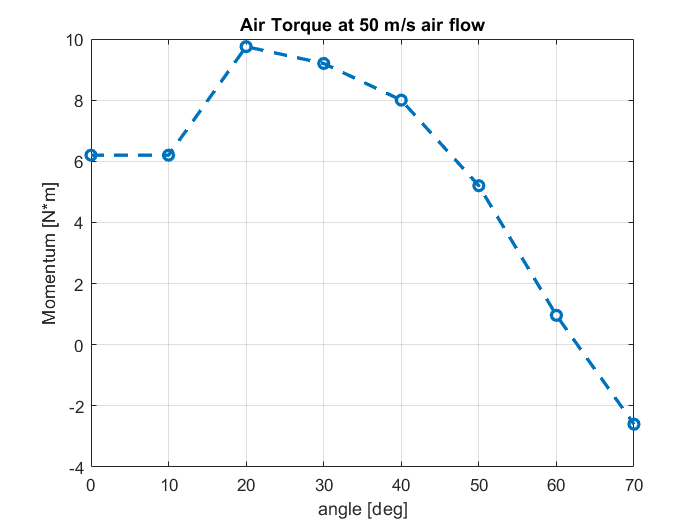

M_cdf = [6.2, 6.2, 9.75, 9.2, 8, 5.2, 0.96, -2.6];

figure
plot(angle,M_cdf,'o--','LineWidth',2)
title('Air Torque at 50 m/s air flow')
xlabel('angle [deg]')
ylabel('Momentum [N*m]')
grid('on')

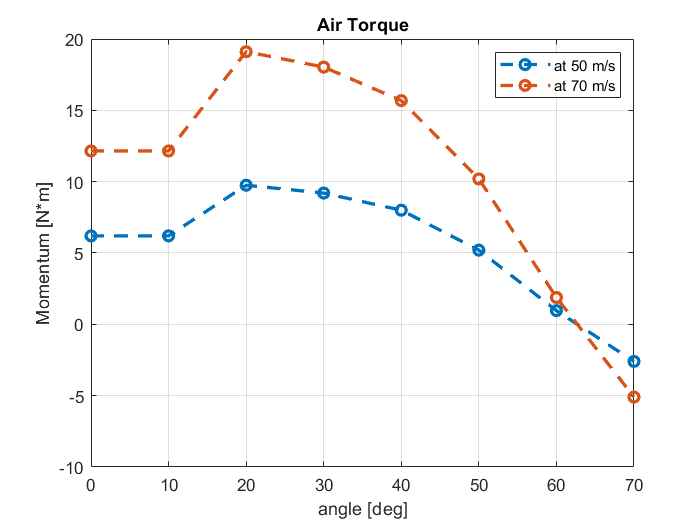

% the real velocity is
v_real = 70 ;  % [m/s]
v_cdf = 50;     % [m/s]

M_scaled = M_cdf*(v_real/v_cdf)^2;

figure
plot(angle,M_cdf,'o--',angle,M_scaled,'o--','LineWidth',2)
title('Air Torque')
xlabel('angle [deg]')
ylabel('Momentum [N*m]')
legend('at 50 m/s','at 70 m/s','Location','northeast')
grid('on')

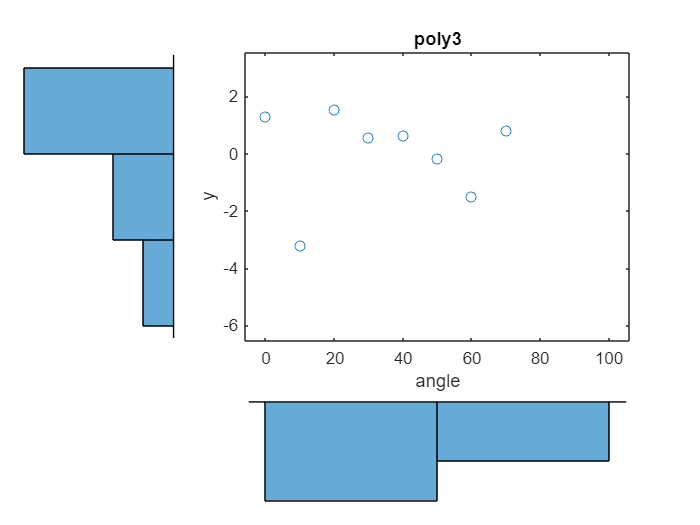

% Polynomial fit
mdl_T=fitlm(angle,M_scaled,"poly3");
figure
scatterhist(angle,mdl_T.Residuals.Raw,"Direction","out","Location","SouthWest")
title('poly3')

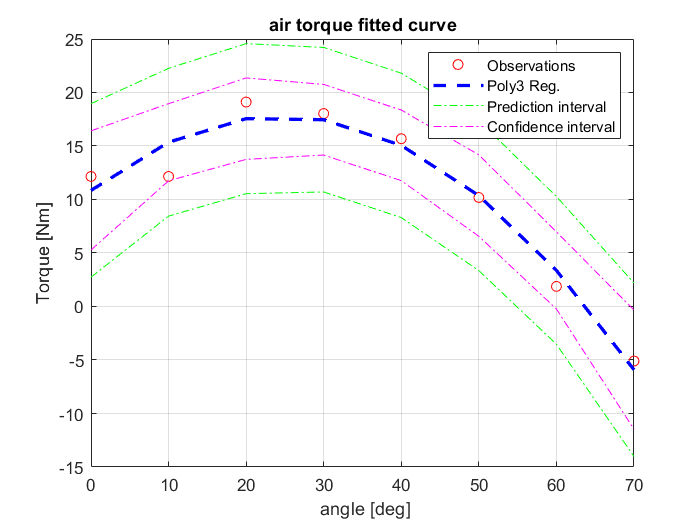

[M_scaled_hat,ci_T]=predict(mdl_T,angle',"Alpha",0.05,"Prediction","curve");
[~,cp_T]=predict(mdl_T,angle',"Alpha",0.05,"Prediction","observation");

%22.143 + 1.15408 x - 0.023503 x^2 + 5.05051*10^-7 x^3 symbolic fit from
%mathematica

figure
plot(angle,M_scaled,"or");
hold on
plot(angle,M_scaled_hat,"--b","LineWidth",2)
plot(angle,cp_T(:,1),"-.g")
plot(angle,cp_T(:,2),"-.g")
plot(angle,ci_T(:,1),"-.m")
plot(angle,ci_T(:,2),"-.m")
hold off
title('air torque fitted curve')
xlabel(' angle [deg]')
ylabel('Torque [Nm]')
legend(["Observations","Poly3 Reg.","Prediction interval","","Confidence interval",""])
grid('on')